The kernel super class allows addition subtraction multiplication and division.

A kernel can then be made periodic in a given dimension or set of dimensions with an enforced period.

A kernel matrix can then be constructed using the build method of a kernel.

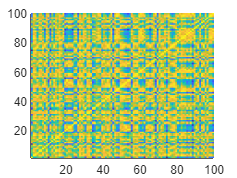

clear all
close all
clc

xx = lhsdesign(100,3);

a = EQ(3,[1 3 2]);

b = Matern52(2,2);

c = RQ(0.1,0.1);

d = (c+a)*b;

e = c + (a.periodic(2,1))+b.periodic([1 3],[0.2]);

K = e.build(xx,xx);

figure(1)
clf(1)
pcolor(K)
shading flat